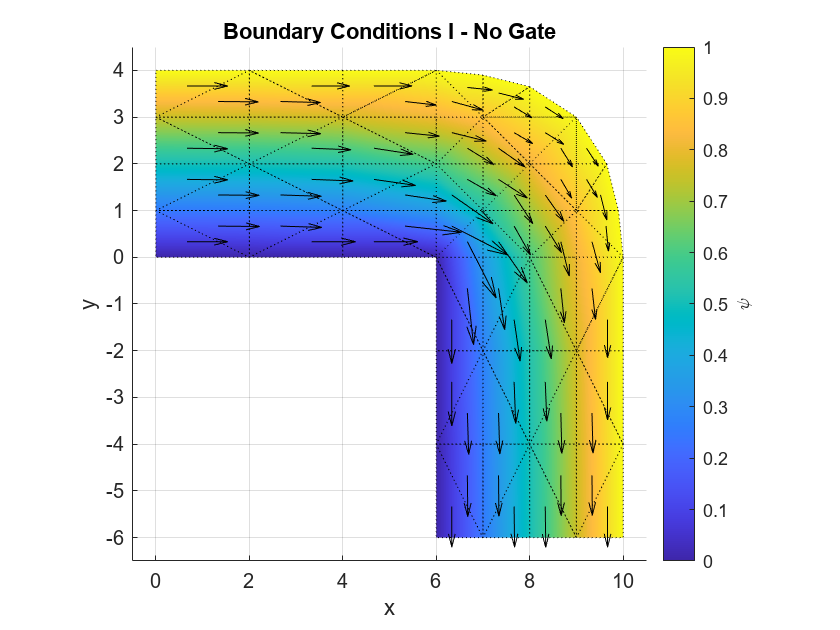

clear; close all

u = readmatrix("u_I.dat");
u = u(2:end);

Vec = readmatrix("grad_I.dat");

nodes = readmatrix("hw5.nodes.dat");
xNodes = nodes(:, 2);
yNodes = nodes(:, 3);
elemsJunk = readmatrix("hw5.elems.dat");
elems = elemsJunk(:, 2:4);

figure;
[h] = Plot2dTriMesh(xNodes, yNodes, elems, u, Vec);
title('Boundary Conditions I - No Gate')
xlim([-0.5, 10.5]);
ylim([-6.5, 4.5])
c = colorbar;
c.Label.String = "$\psi$";
c.Label.Interpreter = "latex";
exportgraphics(gcf, 'NoGate.png', 'Resolution',300);


u = readmatrix("u_II.dat");
u = u(2:end);
Vec = readmatrix("grad_II.dat");
figure;
[h] = Plot2dTriMesh(xNodes, yNodes, elems, u, Vec);
title('Boundary Conditions II - Short Gate')
plot([8, 9], [2, 3], 'k', 'LineWidth',2)
xlim([-0.5, 10.5]);
ylim([-6.5, 4.5])
c = colorbar;
c.Label.String = "$\psi$";
c.Label.Interpreter = "latex";
exportgraphics(gcf, 'ShortGate.png', 'Resolution',300);
relVec = Vec( find(prod(elems - 25, 2) == 0) , :);
mean(relVec, 1)

ans =     0.0710   -0.1392


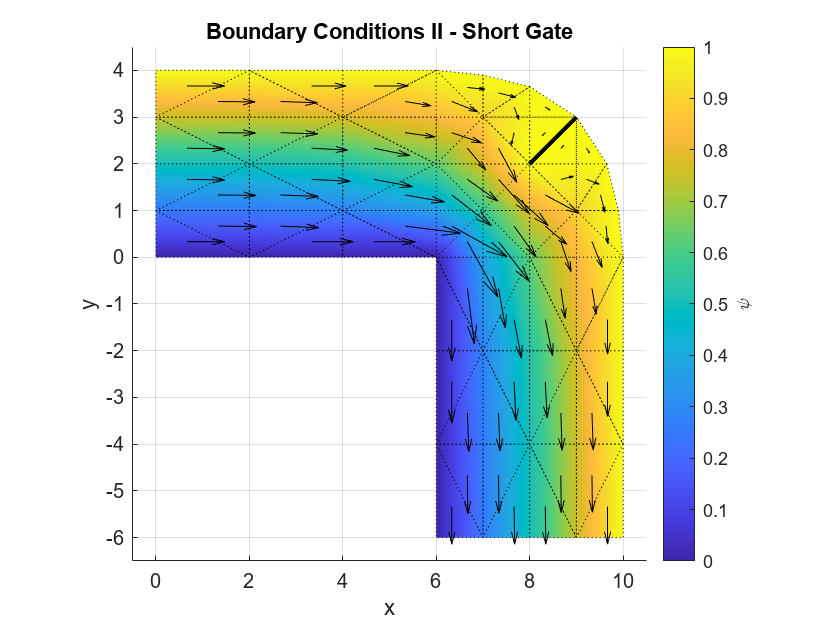

exportgraphics(gcf, 'ShortGate.png', 'Resolution',300);

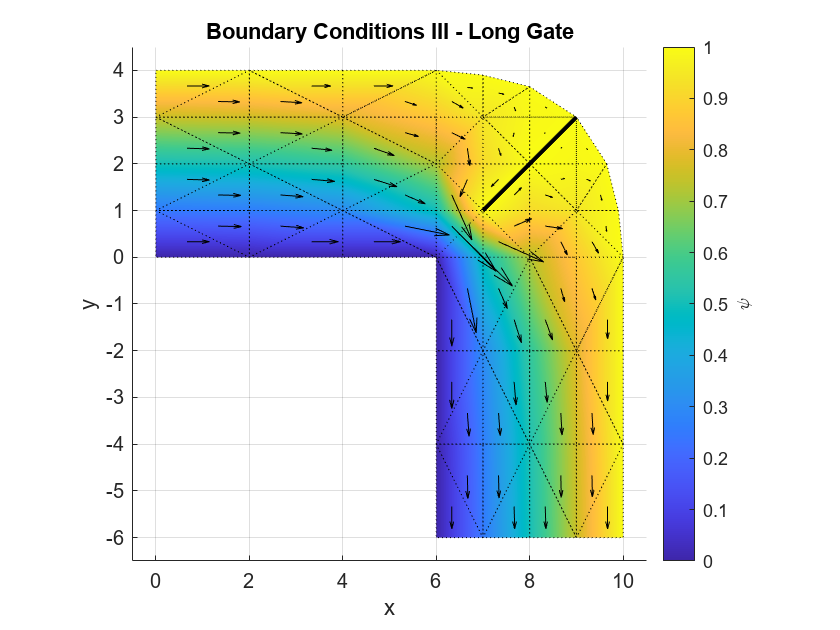


u = readmatrix("u_III.dat");
u = u(2:end);
Vec = readmatrix("grad_III.dat");
figure;
[h] = Plot2dTriMesh(xNodes, yNodes, elems, u, Vec);
title('Boundary Conditions III - Long Gate')
plot([7, 9], [1, 3], 'k', 'LineWidth',2)
xlim([-0.5, 10.5]);
ylim([-6.5, 4.5])
c = colorbar;
c.Label.String = "$\psi$";
c.Label.Interpreter = "latex";
exportgraphics(gcf, 'LongGate.png', 'Resolution',300);

relVec = Vec( find(prod(elems - 21, 2) == 0) , :);
mean(relVec, 1)

ans =     0.1384   -0.3219
